    clear; close all;

N_type = 5; N_slice = 1; N_data = 100;
N_clip = N_type*N_slice*N_data;

oct_diff = [0 200 400 800 1600 3200 6400 11025];  % Freq Normalized interval
oct_alpha = 0.02;  % tunable

N_freq_intvl = (length(oct_diff)-1);
feature = zeros(N_clip, N_freq_intvl*2);
style = zeros(N_clip, 1);

load('feature.mat','feature');
load('style.mat','style');

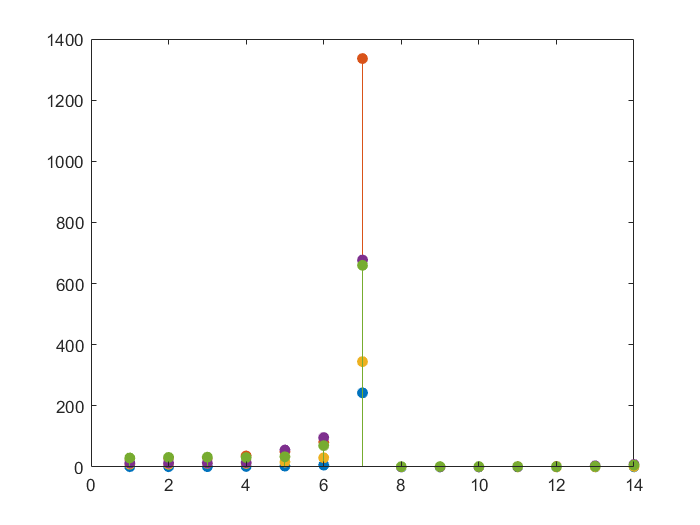

% Different music types features visualization
n = 1:N_freq_intvl*2;
for i = 1:1:N_type
    stem(n, feature(N_slice*N_data*(i-1)+1,:),'filled');
    hold on
end
hold off

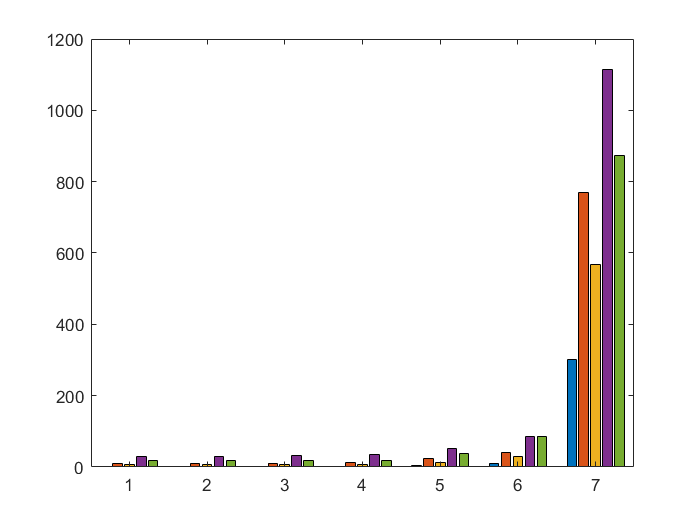

n = 1:N_freq_intvl*2;
x = sum(feature(1:N_slice*N_data,:))/(N_slice*N_data);
for i = 2:1:N_type
    x = vertcat(x, sum(feature(N_slice*N_data*(i-1)+1:N_slice*N_data*i,:))/(N_slice*N_data));
end
x = x';
bar(x(1:7,:));

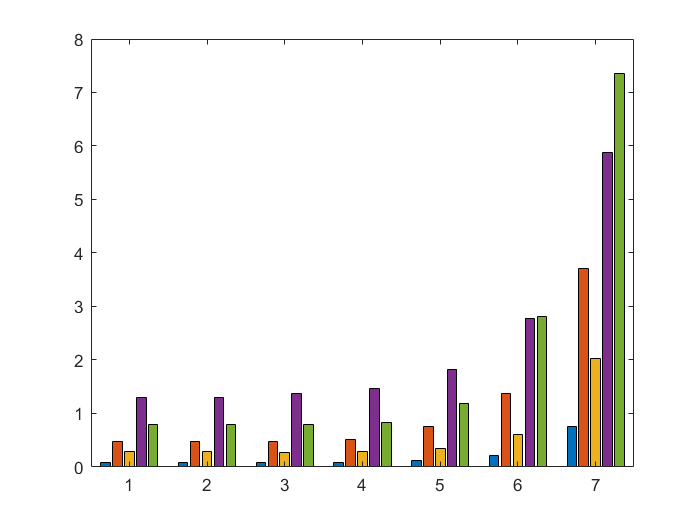

bar(x(8:14,:));

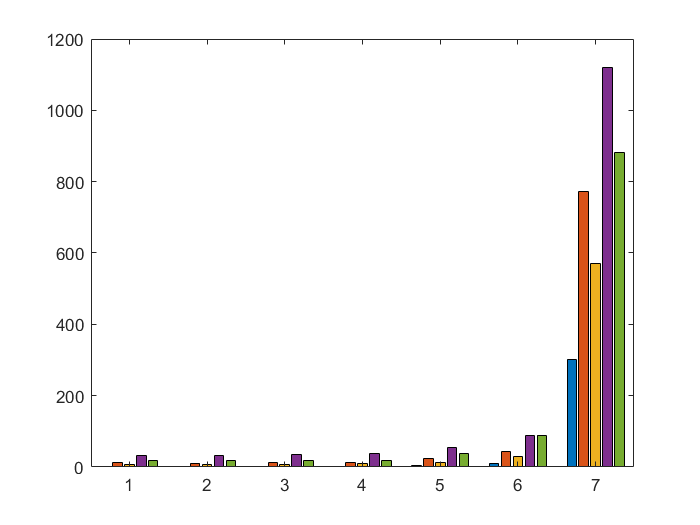

bar(x(1:7,:)+x(8:14,:));

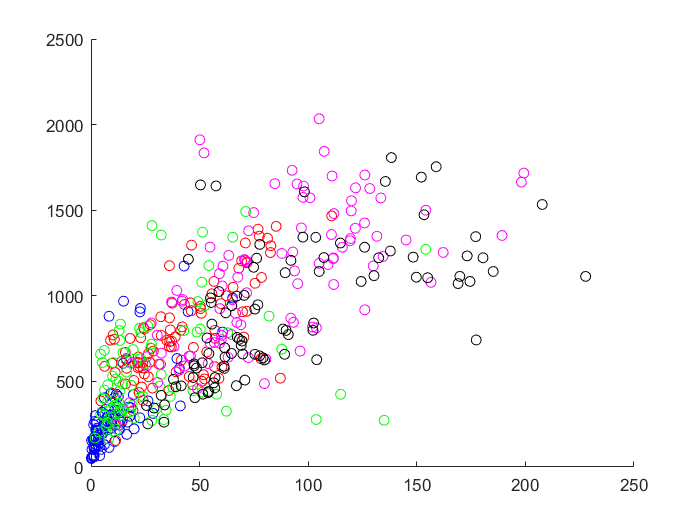

figure;
hold on;
color = 'brgmk';
m = length(color);
for i = 1:1:N_type
    for j = 1:1:N_slice*N_data
        scatter(feature(N_slice*N_data*(i-1)+j,6),feature(N_slice*N_data*(i-1)+j,7)...
            ,36,color(mod(i-1,N_type)+1));
    end
end
hold off;

% % KLT
% for i = 1:1:N_type
%     feature_klt((N_slice*N_data*(i-1)+1):(N_slice*N_data*i),:) = ...
%         klt_audio(feature((N_slice*N_data*(i-1)+1):(N_slice*N_data*i),:));
% end

% figure;
% hold on;
% color = 'brgmk';
% m = length(color);
% for i = 1:1:N_type
%     for j = 1:1:N_slice*N_data
%         scatter(feature_klt(N_slice*N_data*(i-1)+j,6),feature_klt(N_slice*N_data*(i-1)+j,7)...
%             ,36,color(mod(i-1,N_type)+1));
%     end
% end
% hold off;

% n = 1:N_freq_intvl*2;
% y = sum(feature_klt(1:N_slice*N_data,:))/(N_slice*N_data);
% for i = 2:1:N_type
%     y = vertcat(y, sum(feature_klt(N_slice*N_data*(i-1)+1:N_slice*N_data*i,:))/(N_slice*N_data));
% end
% y = y';
% bar(y(1:7,:));

% Data splitting
alpha_spilt = 0.2;   % training & testing data split factor
num_train = N_clip*(1-alpha_spilt);
num_test = N_clip*alpha_spilt;
% x means feature; y means label
x_train = zeros(num_train, N_freq_intvl*2);
x_test = zeros(num_test, N_freq_intvl*2);
y_train = zeros(num_train, 1);
y_test = zeros(num_test, 1);
% Random and class-uniform distribution & 
for i = 1:1:N_type
    indices = randperm(N_slice*N_data);
    x_tmp = feature((N_slice*N_data*(i-1)+1):(N_slice*N_data*i),:);
    y_tmp = style((N_slice*N_data*(i-1)+1):(N_slice*N_data*i),:);
    x_tmp = x_tmp(indices,:);
    y_tmp = y_tmp(indices,:);
    x_train((N_slice*N_data*(1-alpha_spilt)*(i-1)+1):(N_slice*N_data*(1-alpha_spilt)*i),:) = ...
        x_tmp(1:N_slice*N_data*(1-alpha_spilt),:);
    x_test((N_slice*N_data*alpha_spilt*(i-1)+1):(N_slice*N_data*alpha_spilt*i),:) = ...
        x_tmp(N_slice*N_data*(1-alpha_spilt)+1:N_slice*N_data,:);
    y_train((N_slice*N_data*(1-alpha_spilt)*(i-1)+1):(N_slice*N_data*(1-alpha_spilt)*i),:) = ...
        y_tmp(1:N_slice*N_data*(1-alpha_spilt),:);
    y_test((N_slice*N_data*alpha_spilt*(i-1)+1):(N_slice*N_data*alpha_spilt*i),:) = ...
        y_tmp(N_slice*N_data*(1-alpha_spilt)+1:N_slice*N_data,:);
end

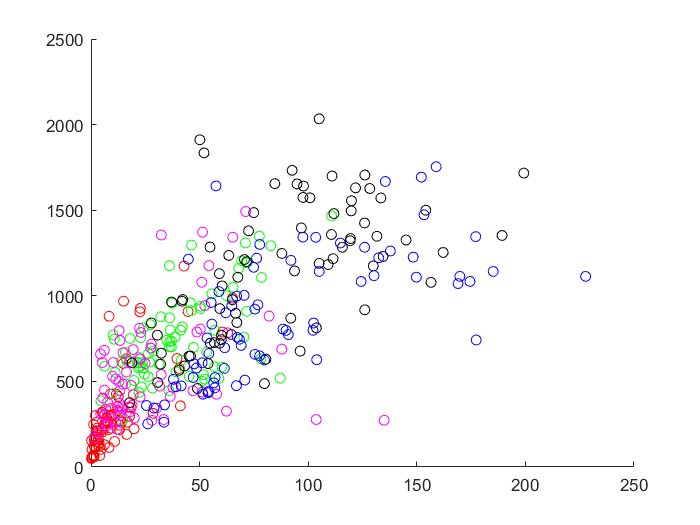

% KLT
% for i = 1:1:N_type
%     x_train((N_slice*N_data*(1-alpha_spilt)*(i-1)+1):(N_slice*N_data*(1-alpha_spilt)*i),:) = ...
%         klt_audio(x_train((N_slice*N_data*(1-alpha_spilt)*(i-1)+1):(N_slice*N_data*(1-alpha_spilt)*i),:));
% end
[x_train_klt, X_mean_klt, A_klt, m_klt] = klt_audio_train(x_train, N_type);

figure;
hold on;
color = 'brgmk';
m = length(color);
for i = 1:1:N_type*N_slice*N_data*(1-alpha_spilt)
    scatter(x_train(i,6),x_train(i,7)...
        ,36,color(mod(y_train(i),N_type)+1));
end
hold off;

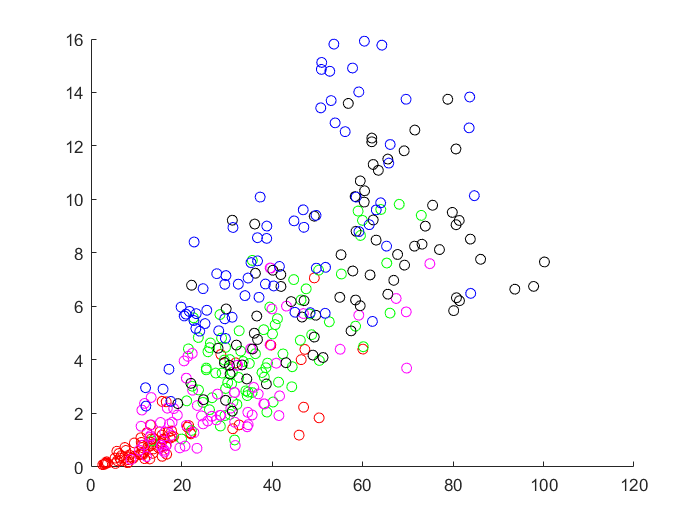


figure;
hold on;
color = 'brgmk';
m = length(color);
for i = 1:1:N_type*N_slice*N_data*(1-alpha_spilt)
    scatter(x_train_klt(i,6),x_train_klt(i,7)...
        ,36,color(mod(y_train(i),N_type)+1));
end
hold off;

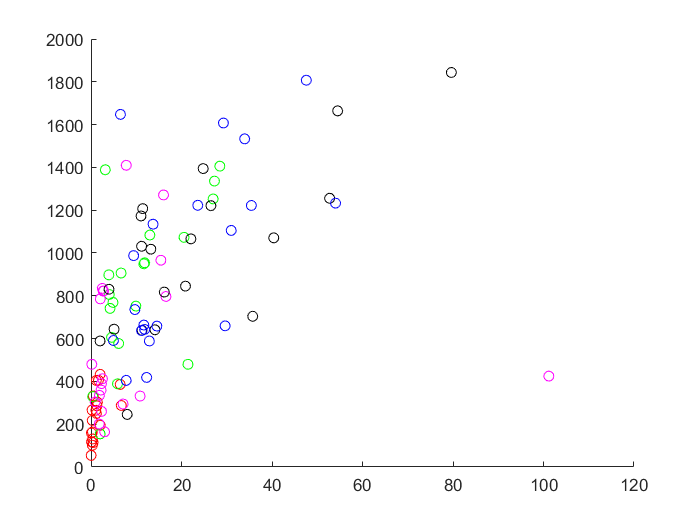

x_test_klt = klt_audio_test(x_test, X_mean_klt, A_klt, m_klt);

figure;
hold on;
color = 'brgmk';
m = length(color);
for i = 1:1:N_type*N_slice*N_data*(alpha_spilt)
    scatter(x_test(i,1),x_test(i,7)...
        ,36,color(mod(y_test(i),N_type)+1));
end
hold off;

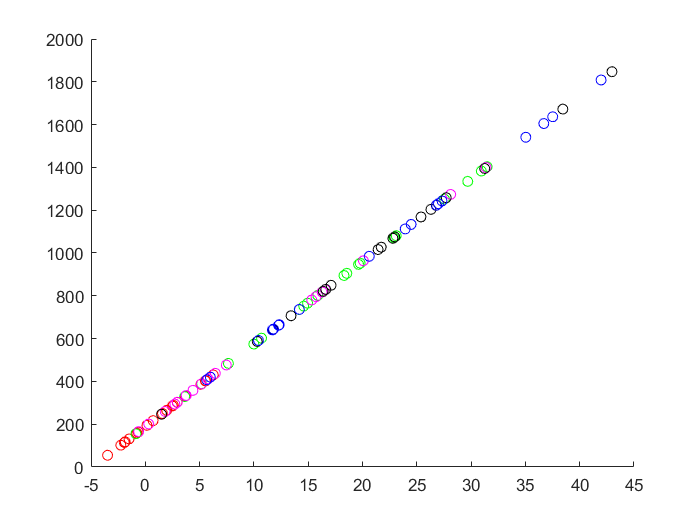


figure;
hold on;
color = 'brgmk';
m = length(color);
for i = 1:1:N_type*N_slice*N_data*(alpha_spilt)
    scatter(x_test_klt(i,1),x_test_klt(i,7)...
        ,36,color(mod(y_test(i),N_type)+1));
end
hold off;

% Data
% x_train, y_train => training feature/label
% x_test, y_test   => testing  feature/label

% % train
% [y_pred_train,model,llh] = mixGaussEm(feature_klt',style');
% num_correct = sum(style==y_pred_train')
% acc_train = num_correct/(N_type*N_slice*N_data)*100

% train
[y_pred_train,model,llh] = mixGaussEm(x_train_klt',y_train');

EM for Gaussian mixture: running ... 


num_correct = sum(y_train==y_pred_train')

num_correct = 187

acc_train = num_correct/(N_type*N_slice*N_data*(1-alpha_spilt))*100    % training performance

acc_train = 46.7500


% predict
y_pred_test = mixGaussPred(x_test_klt',model);
num_correct = sum(y_test==y_pred_test')

num_correct = 20

acc_test = num_correct/(N_type*N_slice*N_data*alpha_spilt)*100 

acc_test = 20